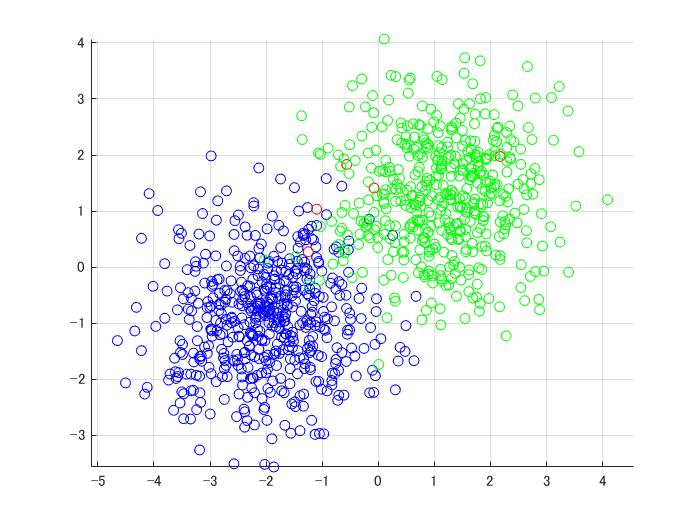

d = 2;
k = 3;
n = 1000;
[X, t] = kmeansRnd(d,k,n);
plotClass(X,t);

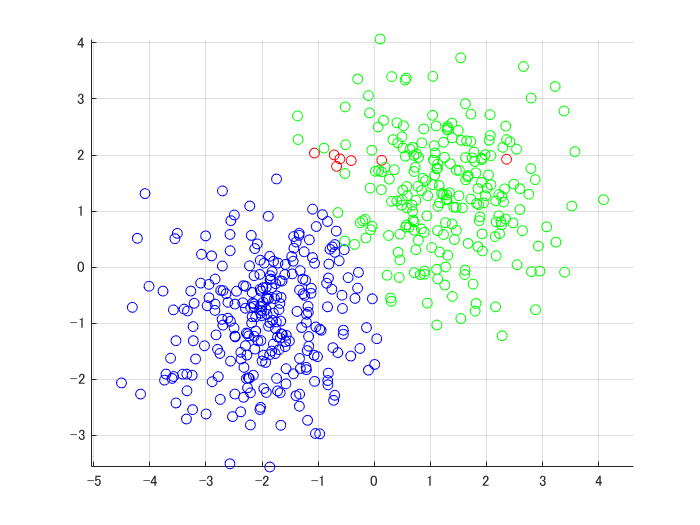


m = floor(n/2);
X1 = X(:,1:m);
X2 = X(:,(m+1):end);
t1 = t(1:m);
model = nbGauss(X1,t1);
y2 = nbGaussPred(model,X2);
plotClass(X2,y2);